# Chapter 2: Statistical Learning

## 2.3 Lab: Introduction to R

### 2.3.1 Basic Commands

clear all; clc; close all
x = [1, 3, 2, 5];
x

x =      1     3     2     5


x = [1, 6, 2];
x

x =      1     6     2


y = [1, 4, 3];

length(x)

ans = 3

length(y)

ans = 3

x + y

ans =      2    10     5


List variables in workspace

who 


Your variables are:

ans  x    y    



Remove items from workspace, freeing up system memory

clear x y
clear all
who

help clear

 clear  Clear variables and functions from memory.
    clear removes all variables from the workspace.
    clear VARIABLES does the same thing.
    clear GLOBAL removes all global variables.
    clear FUNCTIONS removes all compiled MATLAB and MEX-functions.
    Calling clear FUNCTIONS decreases code performance and is usually unnecessary.
    For more information, see the clear Reference page.
 
    clear ALL removes all variables, globals, functions and MEX links.
    clear ALL at the command prompt also clears the base import list.
    Calling clear ALL decreases code performance and is usually unnecessary.
    For more information, see the clear Reference page.
 
    clear IMPORT clears the base import list.  It can only be issued at the 
    command prompt. It cannot be used in a function or a script.
 
    

x = reshape([1, 2, 3, 4],2,2);
x

x =      1     3
     2     4


sqrt(x)

ans =     1.0000    1.7321
    1.4142    2.0000


x^2

ans =      7    15
    10    22


x = randn(50,1)

x =     0.5377
    1.8339
   -2.2588
    0.8622
    0.3188
   -1.3077
   -0.4336
    0.3426
    3.5784
    2.7694


y = x + 50 + 0.1*randn(50,1)

y =    50.4513
   51.8416
   47.6197
   50.7508
   50.3181
   48.8456
   49.4894
   50.3798
   53.5558
   52.8812


corr(x,y)

ans = 0.9967

rng(1303);
randn(50,1)

ans =     0.4770
   -0.8833
   -0.6307
    0.9883
    0.2881
   -0.5965
    0.7636
    0.2613
   -0.0928
   -0.8122


rng(3);
y = randn(50,1)

y =     0.0685
    0.9512
   -0.3448
    0.0359
    1.1221
    0.3237
   -0.4112
   -0.6418
   -0.6615
   -0.2253


mean(y)

ans = -0.0617

var(y)

ans = 0.5410

sqrt(var(y))

ans = 0.7355

std(y)

ans = 0.7355

### 2.3.2 Graphics

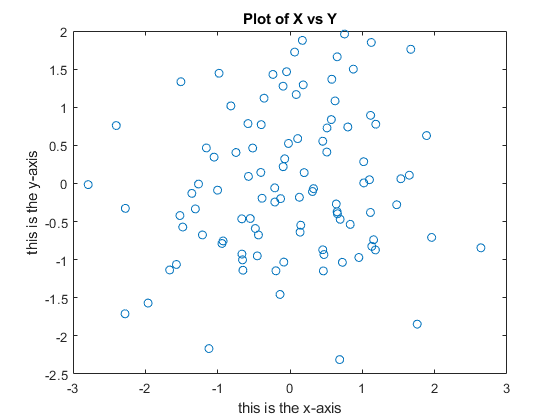

x = randn(100,1);
y = randn(100,1);
plot(x,y,'o');
xlabel 'this is the x-axis'
ylabel 'this is the y-axis'
title 'Plot of X vs Y'

saveas(gcf,'Data/Figure.png')

x = linspace(1,10,10)

x =      1     2     3     4     5     6     7     8     9    10


x = (1:10)

x =      1     2     3     4     5     6     7     8     9    10


x = linspace(-pi,pi,50)

x =    -3.1416   -3.0134   -2.8851   -2.7569   -2.6287   -2.5005   -2.3722   -2.2440   -2.1158   -1.9875   -1.8593   -1.7311   -1.6029   -1.4746   -1.3464   -1.2182   -1.0899   -0.9617   -0.8335   -0.7053   -0.5770   -0.4488   -0.3206   -0.1923   -0.0641    0.0641    0.1923    0.3206    0.4488    0.5770    0.7053    0.8335    0.9617    1.0899    1.2182    1.3464    1.4746    1.6029    1.7311    1.8593    1.9875    2.1158    2.2440    2.3722    2.5005    2.6287    2.7569    2.8851    3.0134    3.1416


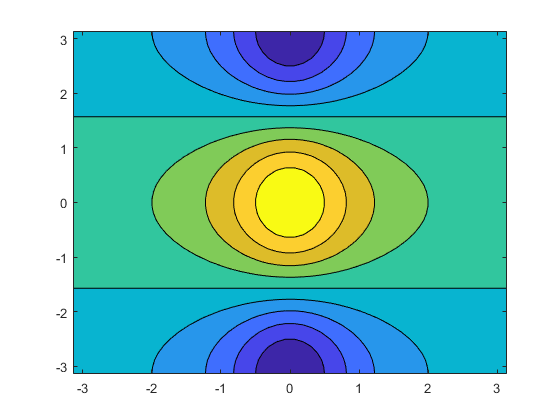

y = x;
[xGrid,yGrid] = meshgrid(x,y);
f = cos(yGrid)./(1 + xGrid.^2);
contourf(xGrid,yGrid,f);

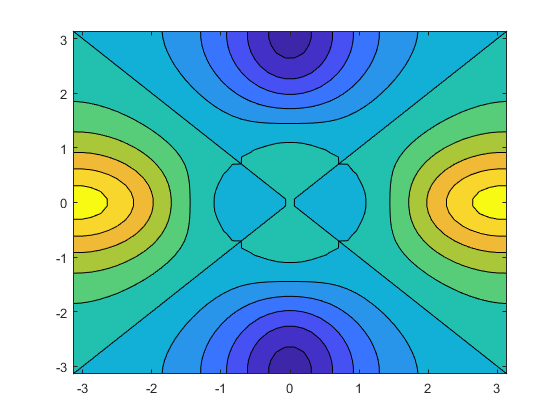

fa = (f - f')/2;
contourf(xGrid,yGrid,fa);

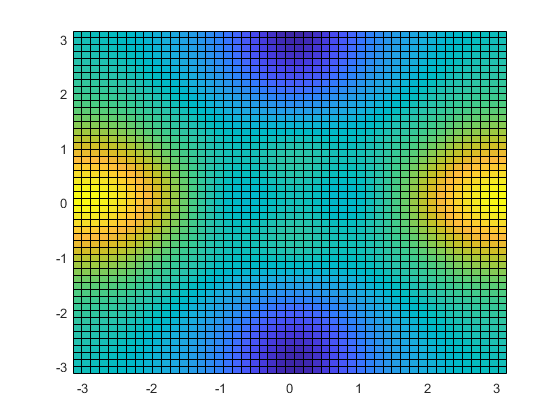

pcolor(xGrid,yGrid,fa);

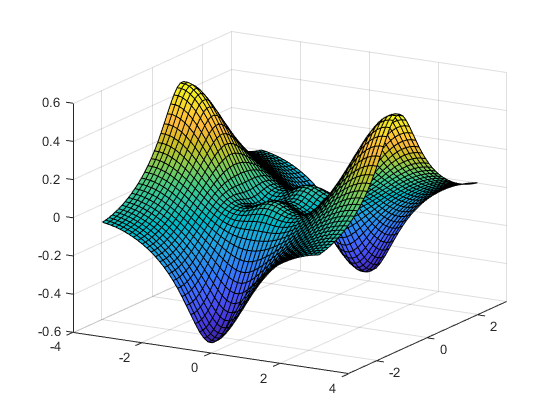

surf(xGrid,yGrid,fa);
view([30 20]);

### 2.3.3 Indexing Data

A = reshape((1:16),4,4);
A

A =      1     5     9    13
     2     6    10    14
     3     7    11    15
     4     8    12    16


A(2,3)

ans = 10

A([1,3],[2,4])

ans =      5    13
     7    15


A(1:3,2:4)

ans =      5     9    13
     6    10    14
     7    11    15


A(1:2,:)

ans =      1     5     9    13
     2     6    10    14


A(:,1:2)

ans =      1     5
     2     6
     3     7
     4     8


A(1,:)

ans =      1     5     9    13


size(A)

ans =      4     4


### 2.3.4 Loading Data

Setup the Import Options and import the data

Auto = readtable('Data\Auto.csv', 'TreatAsEmpty',{'?','NA','N/A'} );
size(Auto)

ans =    397     9


Auto(1:4,:)

ans = 4×9 table
    mpg    cylinders    displacement    horsepower    weight    acceleration    year    origin                name             
    ___    _________    ____________    __________    ______    ____________    ____    ______    _____________________________

    18         8            307            130         3504           12         70       1       {'chevrolet chevelle malibu'}
    15         8            350            165         3693         11.5         70       1       {'buick skylark 320'        }
    18         8            318            150         3436           11         70       1       {'plymouth satellite'       }
    16         8            304      

Remove missing entries

Auto = rmmissing(Auto,1);
size(Auto)

ans =    392     9


Auto.Properties.VariableNames

ans = 1×9 cell array
    {'mpg'}    {'cylinders'}    {'displacement'}    {'horsepower'}    {'weight'}    {'acceleration'}    {'year'}    {'origin'}    {'name'}


### 2.3.5 Additional Graphical and Numerical Summaries

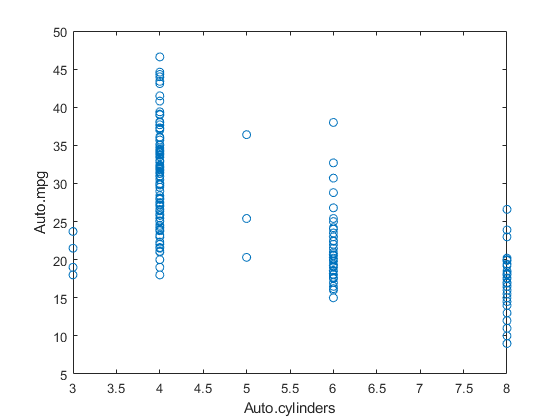

plot(Auto.cylinders,Auto.mpg,'o');
xlabel 'Auto.cylinders'
ylabel 'Auto.mpg'

cylinders = categorical(Auto.cylinders);
% summary(cylinders)

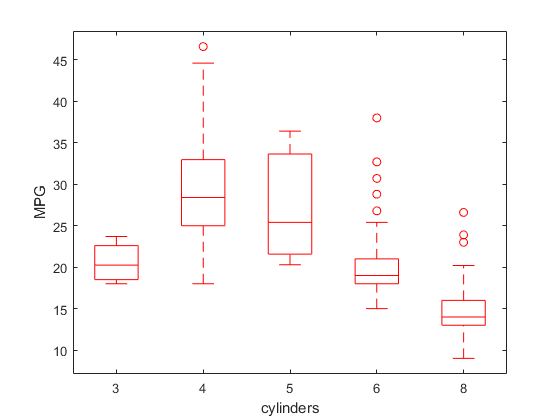

figure
boxplot(Auto.mpg,cylinders,'Colors','r',...
    'Symbol','o')
xlabel 'cylinders'
ylabel 'MPG'

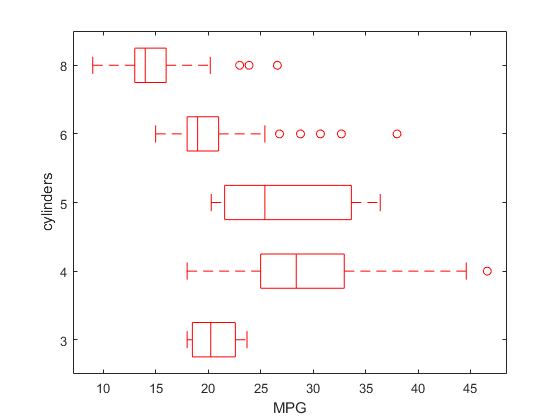

figure
boxplot(Auto.mpg,cylinders,'Colors','r',...
    'Symbol','o','Orientation','horizontal')
xlabel 'MPG'
ylabel 'cylinders'

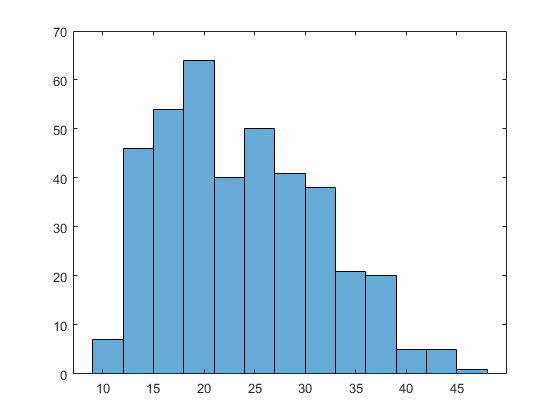

histogram(Auto.mpg)

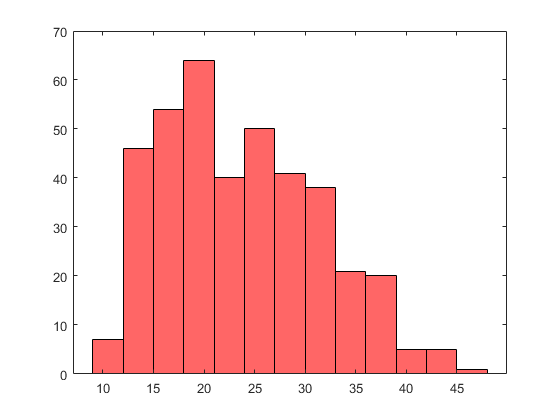

histogram(Auto.mpg,'FaceColor','r')

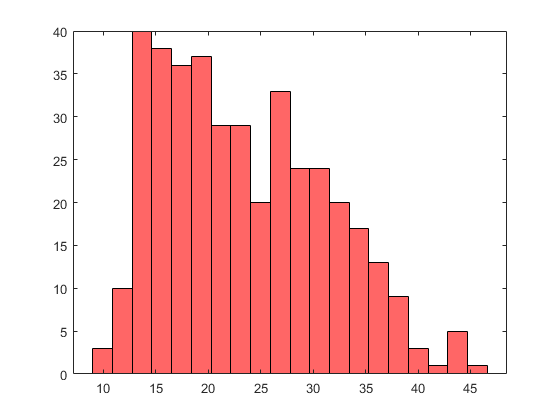

histogram(Auto.mpg,'FaceColor','r','NumBins',20)

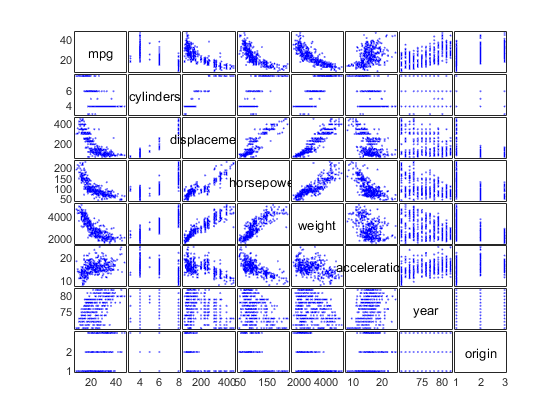

xnames = Auto.Properties.VariableNames;
gplotmatrix(Auto{:,1:end-1},[],[],[],[],[],[],'variable',xnames(1:end-1));

% xnames = {'mpg','displacement','horsepower','weight','acceleration'};
% color = lines(3);
% gplotmatrix(Auto{:,xnames},[],Auto.cylinders,color,[],[],[],'variable',xnames);

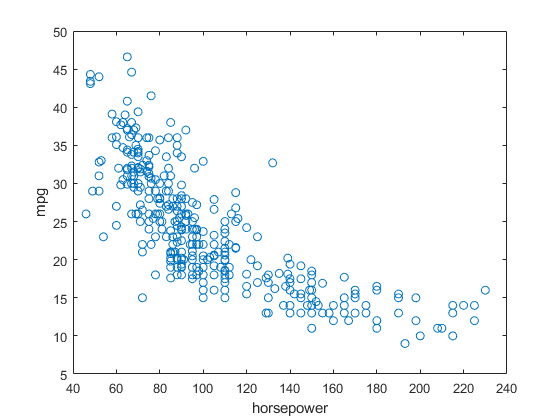

plot(Auto.horsepower,Auto.mpg,'o');
xlabel 'horsepower'
ylabel 'mpg'

summary(Auto)


Variables:

    mpg: 392×1 double

        Values:

            Min           9
            Median    22.75
            Max        46.6

    cylinders: 392×1 double

        Values:

            Min            3     
            Median         4     
            Max            8     

    displacement: 392×1 double

        Values:

            Min             68      
            Median         151      
            Max            455      

    horsepower: 392×1 double

        Values:

            Min             46    
            Median        93.5    
            Max            230    

    weight: 392×1 double

        Values:

            Min          1613 
            Median     2803.5 
            Max          5140 

    acceleration: 392×1 double

        Values:

            Min               8     
            Median         15.5     
            Max            24.8     


summary(Auto(:,'mpg'))


Variables:

    mpg: 392×1 double

        Values:

            Min           9
            Median    22.75
            Max        46.6

